clc;
clear;


% The following code is generated with filterDesigner

% MATLAB Code
% Generated by MATLAB(R) 25.1 and Signal Processing Toolbox 25.1.
% Generated on: 12-Nov-2025 19:01:11

% Equiripple Lowpass filter designed using the FIRPM function.

% All frequency values are in kHz.
Fs = 30;  % Sampling Frequency

Fpass = 4.6;             % Passband Frequency
Fstop = 5.9;             % Stopband Frequency
Dpass = 0.011512416822;  % Passband Ripple
Dstop = 0.001;           % Stopband Attenuation
dens  = 20;              % Density Factor

% Calculate the order from the parameters using FIRPMORD.
[N, Fo, Ao, W] = firpmord([Fpass, Fstop]/(Fs/2), [1 0], [Dpass, Dstop]);

% Calculate the coefficients using the FIRPM function.
b  = firpm(N, Fo, Ao, W, {dens});
Hd2 = dfilt.dffir(b);
% end generated code

% Quantize the filter coeffs
Hdq2 = dfilt.dffir;
quantized_len = 11;
Hdq2.Numerator = fi(Hd2.Numerator,1, quantized_len, quantized_len);

a = Hd2.Numerator;

p = 10;
p_c = 11;
n_c = 11;
r = 0;

A = sum(abs(Hdq2.Numerator));
g = ceil(log2(A));
n = p - 2;

bitspec = [p, p_c, n_c, r, g, n];

[y_fixpt,y_float,y_error] = FIR_Experiment('sine', a, bitspec);

I/O word length: 10
MAC input format: s10.9
Coefficient format: s11.11
Product pipeline register format: s21.20
Accumulator register format: s22.20
MAC output format: s10.8
FIR/MAC Simulation
Execution mode: override
Signal length : 315
Filter taps   : 59
FIR/MAC Simulation
Execution mode: fixed-point
Signal length : 315
Filter taps   : 59


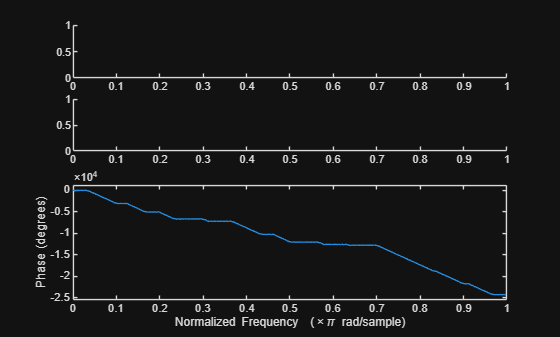

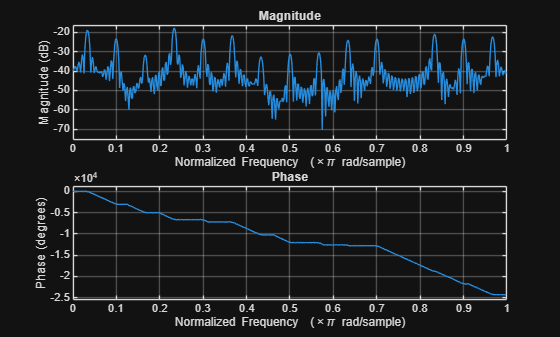


freqz(y_error);


[y_fixpt,y_float,y_error] = FIR_Experiment('rand', a, bitspec);

I/O word length: 10
MAC input format: s10.9
Coefficient format: s11.11
Product pipeline register format: s21.20
Accumulator register format: s22.20
MAC output format: s10.8
FIR/MAC Simulation
Execution mode: override
Signal length : 315
Filter taps   : 59
FIR/MAC Simulation
Execution mode: fixed-point
Signal length : 315
Filter taps   : 59


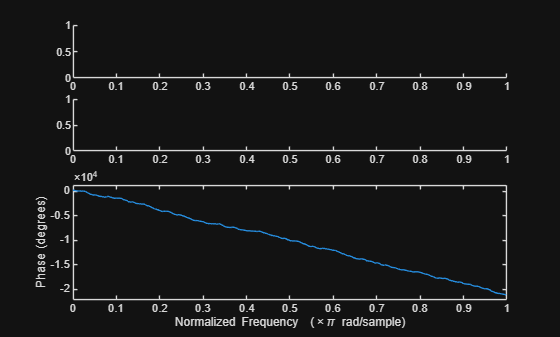

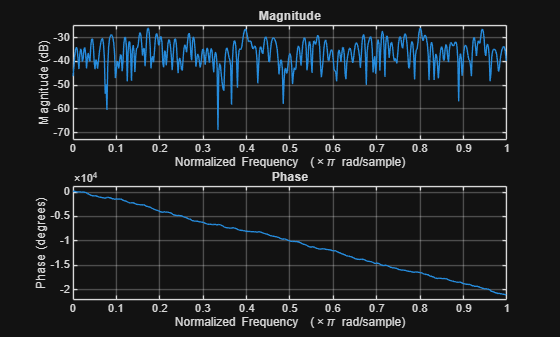


freqz(y_error);


[y_fixpt,y_float,y_error] = FIR_Experiment('rand', a, bitspec);

I/O word length: 10
MAC input format: s10.9
Coefficient format: s11.11
Product pipeline register format: s21.20
Accumulator register format: s22.20
MAC output format: s10.8
FIR/MAC Simulation
Execution mode: override
Signal length : 315
Filter taps   : 59
FIR/MAC Simulation
Execution mode: fixed-point
Signal length : 315
Filter taps   : 59



%c

% compare to the quantized filter
a = Hdq2.Numerator;

errors = zeros(1,9);
idx = 1;
for i = -4:4
    bitspec(6) = n + i; 
    [y_fixpt,y_float,y_error] = FIR_Experiment('rand', a, bitspec);
    errors(idx) = mean(y_error.^2);
    idx = idx + 1;
end

I/O word length: 10
MAC input format: s10.9
Coefficient format: s11.11
Product pipeline register format: s21.20
Accumulator register format: s22.20
MAC output format: s10.4
FIR/MAC Simulation
Execution mode: override
Signal length : 315
Filter taps   : 59
FIR/MAC Simulation
Execution mode: fixed-point
Signal length : 315
Filter taps   : 59
I/O word length: 10
MAC input format: s10.9
Coefficient format: s11.11
Product pipeline register format: s21.20
Accumulator register format: s22.20
MAC output format: s10.5
FIR/MAC Simulation
Execution mode: override
Signal length : 315
Filter taps   : 59
FIR/MAC Simulation
Execution mode: fixed-point
Signal length : 315
Filter taps   : 59
I/O word length: 10
MAC input format: s10.9
Coefficient format: s11.11
Product pipeline register format: s21.20
Accumulator register format: s22.20
MAC output format: s10.6
FIR/MAC Simulation
Execution mode: override
Signal length : 315
Filter taps   : 59
FIR/MAC Simulation
Execution mode: fixed-point
Signal length


errors_dB = 10*log10(errors);

% d
bitspec = [p, p_c, n_c, r, g, n];

[y_fixpt,y_float,y_error] = FIR_Experiment('rand', a, bitspec);

I/O word length: 10
MAC input format: s10.9
Coefficient format: s11.11
Product pipeline register format: s21.20
Accumulator register format: s22.20
MAC output format: s10.8
FIR/MAC Simulation
Execution mode: override
Signal length : 315
Filter taps   : 59
FIR/MAC Simulation
Execution mode: fixed-point
Signal length : 315
Filter taps   : 59


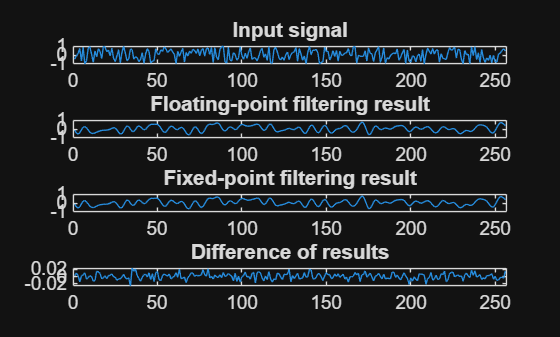

I/O word length: 10
MAC input format: s10.9
Coefficient format: s11.11
Product pipeline register format: s21.20
Accumulator register format: s22.20
MAC output format: s10.8
FIR/MAC Simulation
Execution mode: override
Signal length : 315
Filter taps   : 59
FIR/MAC Simulation
Execution mode: fixed-point
Signal length : 315
Filter taps   : 59
I/O word length: 10
MAC input format: s10.9
Coefficient format: s11.11
Product pipeline register format: s20.19
Accumulator register format: s21.19
MAC output format: s10.8
FIR/MAC Simulation
Execution mode: override
Signal length : 315
Filter taps   : 59
FIR/MAC Simulation
Execution mode: fixed-point
Signal length : 315
Filter taps   : 59
I/O word length: 10
MAC input format: s10.9
Coefficient format: s11.11
Product pipeline register format: s19.18
Accumulator register format: s20.18
MAC output format: s10.8
FIR/MAC Simulation
Execution mode: override
Signal length : 315
Filter taps   : 59
FIR/MAC Simulation
Execution mode: fixed-point
Signal length


errors2 = zeros(1,13);
idx = 1;
for i = 0:12
    bitspec(4) = i; 
    [y_fixpt,y_float,y_error] = FIR_Experiment('rand', a, bitspec);
    errors2(idx) = mean(y_error.^2);
    idx = idx + 1;
end


errors2_dB = 10*log10(errors2);

